# Atividade 7 - Implementando um circuito eletrônico em software 

## Boas práticas

clear;                %%% limpando as variáveis
close all;            %%% fechando todas as figuras
clc;                  %%% limpando a tela

## Variáveis Simbólicas

syms t w

## Função de Entrada x(t)

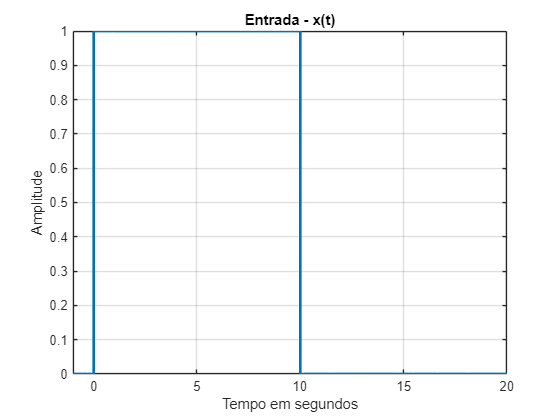

%%% Função xt - Pulso retangular 
xt = rectangularPulse(0,10,t);

%%% Plot da Função xt 
fplot(xt,[-1 20],'LineWidth',2);
title("Entrada - x(t)")
xlabel("Tempo em segundos"); 
ylabel("Amplitude");
grid;

## Resposta Impulsiva g(t)

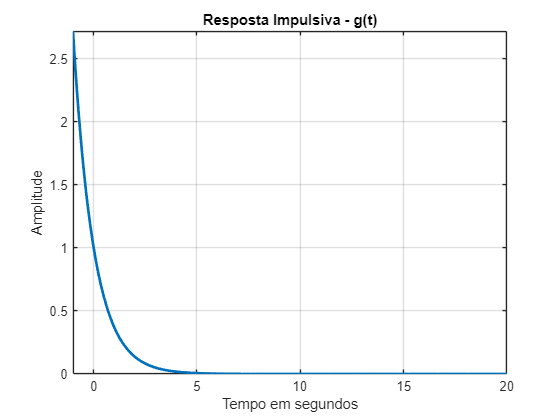

%%% Função gt - exponencial 
gt = exp(-t)*heaviside(t);

%%% Plot da Função gt
fplot(gt,[-1 20],'LineWidth',2);
title("Resposta Impulsiva - g(t)")
xlabel("Tempo em segundos"); 
ylabel("Amplitude");
grid;

## Fourier da Função x(t)

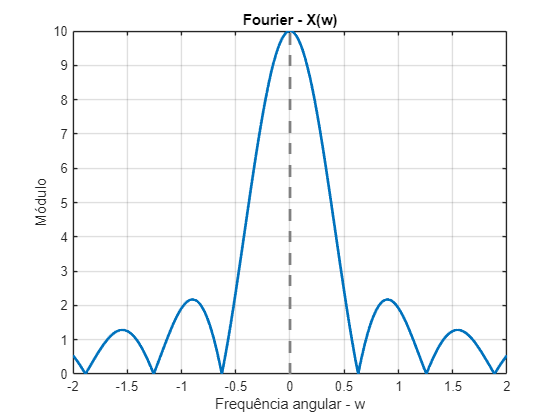

%%% Fourier da função xt transformando para a função Xw
Xw  = fourier(xt,t,w);

%%% Plot do Fourier de Xw
fplot(abs(Xw),[-2 2],'LineWidth',2); 
title("Fourier - X(w)")
xlabel("Frequência angular - w"); 
ylabel("Módulo");
grid;

## Fourier da Função g(t)

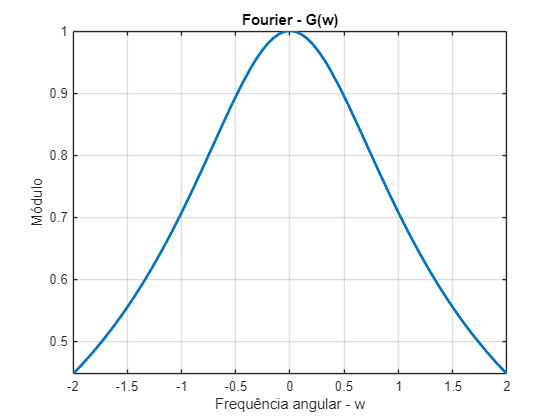

%%% Fourier da função gt transformando para a função Gw
% Gw = fourier(gt,t,w);
Gw = 1/((1i*w)+1);

%%% Plot do Fourier de Gw
fplot(abs(Gw),[-2 2],'LineWidth',2); 
title("Fourier - G(w)");
xlabel("Frequência angular - w"); 
ylabel("Módulo");
grid;

## Função de Saída  no domínio de Fourier

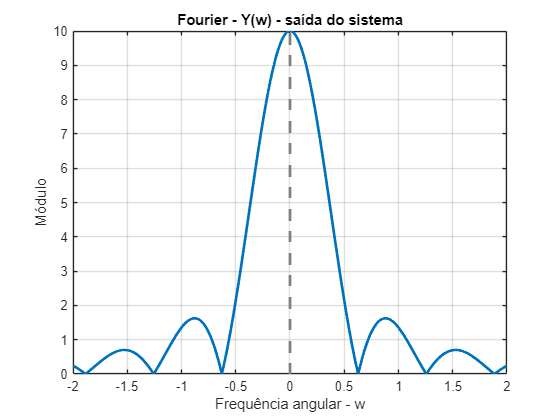

%%% Cálculo da função Yw
Yw = Gw*Xw;

%%% Plot do Fourier de Yw
fplot(abs(Yw),[-2 2],'LineWidth',2); 
title("Fourier - Y(w) - saída do sistema");
xlabel("Frequência angular - w"); 
ylabel("Módulo");
grid;

## Função de Saída no domínio do tempo

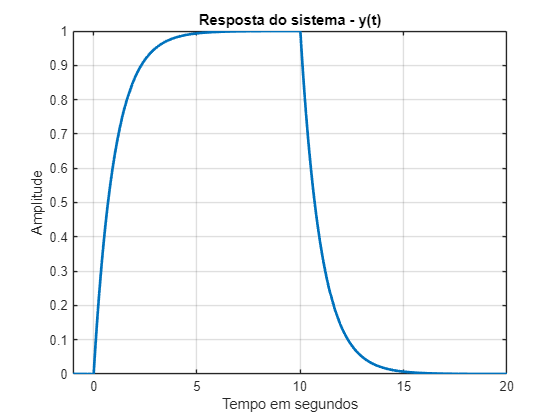

%%% Anti-Transformada de Fourier para levar Yw para yt 
yt = ifourier(Yw,w,t);

%%% Plot da Anti-Transformada de Fourier de yt 
fplot(yt,[-1 20],'LineWidth',2); 
title("Resposta do sistema - y(t)");
xlabel("Tempo em segundos"); 
ylabel("Amplitude");
grid;